# Robotics Midterm Test - 2019-04-29

## Exercise 1

% n=2;
% q = sym('q', [1 n],'real');
% % qd = sym('qd', [1 n]);
% % qdd = sym('qdd', [1 n]); 
% % d = sym('d', [1 n]);
% a = sym('a', [1 3],'real');
% % l = sym('l', [1 n]);
% m = sym('m', [1 n],'real');

## Ma

% 
% Ma=[a(1)+a(2)*(q(1)^2) a(2);a(2),a(2)]
% [isPD] = isPositiveDefinite(Ma,1)% method 2 doesn't work
% diag(Ma)
% ldet=det(Ma)
% 
% %%conditions
% cond=[ldet<0,a(1)>a(2),a(2)>0]
% posdef=solve(cond)
% %%
% disp("is positive defined but m_1,1 depend of q1")

## Mb

% 
% Mb=[a(1),a(3)*cos(q(2)-q(1));a(3)*cos(q(2)-q(1)),a(2)]
% [isPD] = isPositiveDefinite(Mb,1)% method 2 doesn't work
% diag(Mb)
% ldet=det(Mb)
% %%conditions
% cond=[ldet<0,(a(1)*a(2))>(a(3)^2),a(1)>0,(a(3)^2)>0]
% % cond=[all(eig(Mb))<=0,(a(1)*a(2))>(a(3)^2),a(1)>0,(a(3)^2)>0]
% 
% posdef=solve(cond,a)
% %%
% disp("is positive defined")

## Mc

% 
% Mc=[a(1)+2*a(2)*cos(q(2)),a(1)+a(2)*cos(q(2));a(1)+a(2)*cos(q(2)),a(1)]
% [isPD] = isPositiveDefinite(Mc,1)% method 2 doesn't work
% diag(Mc)
% ldet=simplify(det(Mc))
% cond=[ldet<0,a(1)>(2*a(2)),(2*a(2))>0]
% posdef=solve(cond,a(1:2))
% 
% disp("is not positive defined")

## Md

% 
% Md=[m(1)+m(2),-0.5*m(2);-0.5*m(2),m(2)]
% [isPD] = isPositiveDefinite(Md,1)% method 2 doesn't work
% diag(Md)
% ldet=simplify(det(Md))
% cond=[ldet<0,m(1)>0,m(2)>0]
% posdef=solve(cond,m(1:2))
% 
% disp("is positive defined")

## Exercise 2: PRP Robot

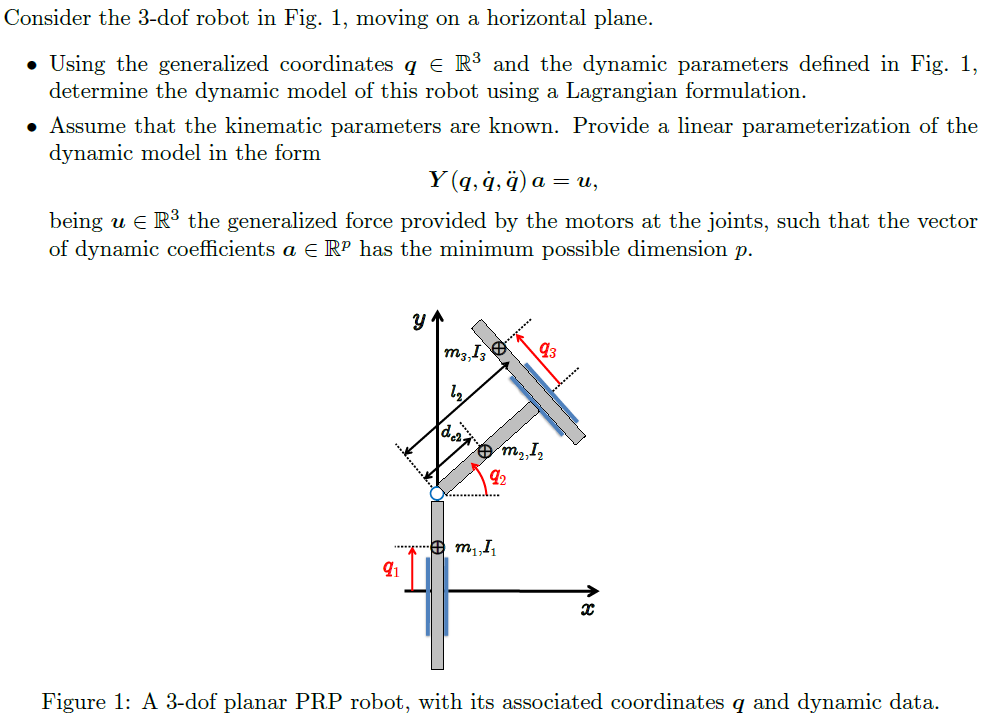

### Automatic attempt

% clear;clc
% sigma = [1,0,1];
% n = length(sigma);
% q = sym('q', [1 n]);
% qd = sym('qd', [1 n]);
% qdd = sym('qdd', [1 n]); 
% d = sym('d', [1 n]);
% a = sym('a', [1 n]);
% l = sym('l', [1 n]);
% m = sym('m', [1 n]);
% I = sym('I', [1 n]);
% 
% %       alpha   a   d   theta
% dhTable = [pi/2  0    q(1)    0;
%            -pi/2  l(2) 0       q(2);
%            0      0   q(3)    0]
% 
% 
% % % L(n)=LINK([theta D A alpha Sigma(optional) Offset(optional)])
% % % Must only specify either THETA or D
% % 
% % L(1) = Link('a', 0, 'alpha', 0*pi/2,  'theta', pi/2,'qlim',[0,10]); % Prismatic
% % L(2) = Link('a', 10, 'alpha', -pi/2, 'd', 0,'qlim',[0,pi]); % Revolute
% % L(3) = Link('a', 0, 'alpha', 0,     'theta', 0,'qlim',[0,10]); % Prismatic
% % prpRobot = SerialLink(L, 'name', 'PRP_Robot ')
% % prpRobot.teach
% % 
% rc = [0,0,q(1);
%     d(2),0,0;
%    0,0,q(3)].'
% I = sym(zeros(3,3,n));
% %rc = []
% for i = 1:n
%  %   rc = [rc [-l(i)+d(i); 0; 0]];
%     I(:,:,i) = diag(sym(strcat({'Ixx','Iyy','Izz'},int2str(i))));
% end
      

% % % M = getM(dhTable, sigma, qd, rc,m,I)
% % % %% Cannot get the proper result
% % 

### Manual Attempt

% This part is isolated from previous section
clear;clc

syms k q1(t) q2(t) q3(t)
sigma = [1,0,1];
n = length(sigma);
q = sym('q', [1 n],'real');
qd = sym('qd', [1 n],'real');
qdd = sym('qdd', [1 n],'real'); 

% Md=sym('Md', [n n],'real');
% Td=qd*Md*qd'
% Md_ = getInertiaMatrixFromKE(Td,qd) dont work
d = sym('d', [1 n],'real');
l = sym('l', [1 n],'real');
m = sym('m', [1 n],'real');
I = sym('I', [1 n],'real');


%Insert manually the global positions of the centers of mass
pc(:,1) = [0 q1];
pc(:,2) = [d(2)*cos(q2), q1+k+d(2)*sin(q2)];
pc(:,3) = [l(2)*cos(q2)-q3*sin(q2), q1+k+l(2)*sin(q2)+q3*cos(q2)]

$$pc = \left(\begin{array}{ccc} 0 & d_{2}\,\cos\left(q_{2}\left(t\right)\right) & l_{2}\,\cos\left(q_{2}\left(t\right)\right)-\sin\left(q_{2}\left(t\right)\right)\,q_{3}\left(t\right)\\ q_{1}\left(t\right) & k+q_{1}\left(t\right)+d_{2}\,\sin\left(q_{2}\left(t\right)\right) & k+q_{1}\left(t\right)+l_{2}\,\sin\left(q_{2}\left(t\right)\right)+\cos\left(q_{2}\left(t\right)\right)\,q_{3}\left(t\right) \end{array}\right)$$

vc = diff(pc,t)

$$vc = \left(\begin{array}{ccc} 0 & -d_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) & -\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right)-\cos\left(q_{2}\left(t\right)\right)\,q_{3}\left(t\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \frac{\partial }{\partial t}q_{1}\left(t\right) & \frac{\partial }{\partial t}q_{1}\left(t\right)+d_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) & \cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right)+\frac{\partial }{\partial t}q_{1}\left(t\right)-\sin\left(q_{2}\left(t\right)\right)\,q_{3}\left(t\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) \end{array}\right)$$

% Substitute the literals just for visualization, as we don't need to
% derivate
vc=subs(vc, [diff(q1(t), t), diff(q2(t), t), diff(q3(t), t)], qd);

vc=subs(vc, [q1,q2,q3], q);
w =[0, qd(2), qd(2)].';
for i=1:n
 T(i) = (1/2)*m(i)*(vc(:,i).'*vc(:,i)) + (1/2)*w(i)*I(i)*w(i);
end
KE = sum(T.')

$$KE = \frac{I_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{I_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{2}\,\left({\left({\mathrm{qd}}_{1}+d_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}+{d_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}\right)}{2}+\frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{3}\,\left({\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{3}\,\cos\left(q_{2}\right)+l_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)-q_{3}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}+{\left({\mathrm{qd}}_{3}\,\sin\left(q_{2}\right)+q_{3}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)+l_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}\right)}{2}$$

% Get the coeficients of the terms. That builds the M matrix
M = getInertiaMatrixFromKE(KE,qd)

$$M = \begin{array}{l} \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & \sigma_{1} & m_{3}\,\cos\left(q_{2}\right)\\ \sigma_{1} & m_{2}\,{d_{2}}^{2}+m_{3}\,{l_{2}}^{2}+m_{3}\,{q_{3}}^{2}+I_{2}+I_{3} & l_{2}\,m_{3}\\ m_{3}\,\cos\left(q_{2}\right) & l_{2}\,m_{3} & m_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=d_{2}\,m_{2}\,\cos\left(q_{2}\right)+l_{2}\,m_{3}\,\cos\left(q_{2}\right)-m_{3}\,q_{3}\,\sin\left(q_{2}\right) \end{array}$$

### Dynamic parameters identification

From the final expression of the Robot dynamic model , it's possible to extract the dynamic parameters, agrouping constant terms.

% It might take a while
[Msubs, dynamicParameters, a] = getDynamicParameters(M,q',l)

>> Getting dynamic coefficients. Might take a while...


paramscell2 = 1×5 cell array
    {1×2 cell}    {1×1 cell}    {1×2 cell}    {1×2 cell}    {1×1 cell}


MSubs second iteration (before re-replacement)


$$Msubs = \left(\begin{array}{ccc} {\mathrm{aa}}_{1} & {\mathrm{aa}}_{2}\,\cos\left(q_{2}\right)+{\mathrm{aa}}_{3}\,\cos\left(q_{2}\right)-{\mathrm{aa}}_{5}\,q_{3}\,\sin\left(q_{2}\right) & {\mathrm{aa}}_{5}\,\cos\left(q_{2}\right)\\ {\mathrm{aa}}_{2}\,\cos\left(q_{2}\right)+{\mathrm{aa}}_{3}\,\cos\left(q_{2}\right)-{\mathrm{aa}}_{5}\,q_{3}\,\sin\left(q_{2}\right) & {\mathrm{aa}}_{5}\,{q_{3}}^{2}+{\mathrm{aa}}_{7} & {\mathrm{aa}}_{2}\\ {\mathrm{aa}}_{5}\,\cos\left(q_{2}\right) & {\mathrm{aa}}_{2} & {\mathrm{aa}}_{5} \end{array}\right)$$

si falla uncomment this line verify  una lineas arriba


$$Msubs = \left(\begin{array}{ccc} a_{1} & a_{2}\,\cos\left(q_{2}\right)-a_{4}\,q_{3}\,\sin\left(q_{2}\right) & a_{4}\,\cos\left(q_{2}\right)\\ a_{2}\,\cos\left(q_{2}\right)-a_{4}\,q_{3}\,\sin\left(q_{2}\right) & a_{4}\,{q_{3}}^{2}+a_{3} & a_{5}\\ a_{4}\,\cos\left(q_{2}\right) & a_{5} & a_{4} \end{array}\right)$$

$$dynamicParameters = \left(\begin{array}{c} m_{1}+m_{2}+m_{3}\\ d_{2}\,m_{2}+l_{2}\,m_{3}\\ m_{2}\,{d_{2}}^{2}+m_{3}\,{l_{2}}^{2}+I_{2}+I_{3}\\ m_{3}\\ l_{2}\,m_{3} \end{array}\right)$$

$$a = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3}\\ a_{4}\\ a_{5} \end{array}\right)$$

% Torque full expression
[C,cac,Csubs] = getCs(Msubs,q',qd')

>> Getting  the Christoffel’sym. Might take a while...


C = 1×3 cell array
    {3×3 sym}    {3×3 sym}    {3×3 sym}


$$cac = \left(\begin{array}{c} -\sin\left(q_{2}\right)\,\left(a_{2}\,{{\mathrm{qd}}_{2}}^{2}+2\,a_{4}\,{\mathrm{qd}}_{3}\,{\mathrm{qd}}_{2}\right)-a_{4}\,q_{3}\,{{\mathrm{qd}}_{2}}^{2}\,\cos\left(q_{2}\right)\\ q_{3}\,\left(2\,a_{4}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}\right)\\ -q_{3}\,\left(a_{4}\,{{\mathrm{qd}}_{2}}^{2}\right) \end{array}\right)$$

Csubs = 1×3 cell array
    {3×3 sym}    {3×3 sym}    {3×3 sym}


u =simplify( Msubs*qdd.' + cac)

$$u = \begin{array}{l} \left(\begin{array}{c} a_{1}\,{\mathrm{qdd}}_{1}-\sin\left(q_{2}\right)\,\left(a_{2}\,{{\mathrm{qd}}_{2}}^{2}+2\,a_{4}\,{\mathrm{qd}}_{3}\,{\mathrm{qd}}_{2}\right)+{\mathrm{qdd}}_{2}\,\sigma_{1}+a_{4}\,{\mathrm{qdd}}_{3}\,\cos\left(q_{2}\right)-a_{4}\,q_{3}\,{{\mathrm{qd}}_{2}}^{2}\,\cos\left(q_{2}\right)\\ {\mathrm{qdd}}_{2}\,\left(a_{4}\,{q_{3}}^{2}+a_{3}\right)+a_{5}\,{\mathrm{qdd}}_{3}+{\mathrm{qdd}}_{1}\,\sigma_{1}+2\,a_{4}\,q_{3}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}\\ -a_{4}\,q_{3}\,{{\mathrm{qd}}_{2}}^{2}+a_{4}\,{\mathrm{qdd}}_{3}+a_{5}\,{\mathrm{qdd}}_{2}+a_{4}\,{\mathrm{qdd}}_{1}\,\cos\left(q_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{2}\,\cos\left(q_{2}\right)-a_{4}\,q_{3}\,\sin\left(q_{2}\right) \end{array}$$

### Linear parametrization

uY = collect(u,a);
Y = [];
for i = 1:length(a)
    Y = [Y, diff(uY,a(i))];
end
Y

$$Y = \left(\begin{array}{ccccc} {\mathrm{qdd}}_{1} & {\mathrm{qdd}}_{2}\,\cos\left(q_{2}\right)-{{\mathrm{qd}}_{2}}^{2}\,\sin\left(q_{2}\right) & 0 & -q_{3}\,\cos\left(q_{2}\right)\,{{\mathrm{qd}}_{2}}^{2}-2\,{\mathrm{qd}}_{3}\,\sin\left(q_{2}\right)\,{\mathrm{qd}}_{2}+{\mathrm{qdd}}_{3}\,\cos\left(q_{2}\right)-q_{3}\,{\mathrm{qdd}}_{2}\,\sin\left(q_{2}\right) & 0\\ 0 & {\mathrm{qdd}}_{1}\,\cos\left(q_{2}\right) & {\mathrm{qdd}}_{2} & {q_{3}}^{2}\,{\mathrm{qdd}}_{2}-q_{3}\,{\mathrm{qdd}}_{1}\,\sin\left(q_{2}\right)+2\,q_{3}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3} & {\mathrm{qdd}}_{3}\\ 0 & 0 & 0 & -q_{3}\,{{\mathrm{qd}}_{2}}^{2}+{\mathrm{qdd}}_{3}+{\mathrm{qdd}}_{1}\,\cos\left(q_{2}\right) & {\mathrm{qdd}}_{2} \end{array}\right)$$

## Exercise 3 nR

% % This part is isolated from previous section
% clear;clc
% 
% syms k q1(t) q2(t) q3(t)
% sigma = [1,1,1,1,1];
% n = length(sigma);
% q = sym('q', [1 n],'real');
% qd = sym('qd', [1 n],'real');
% qdd = sym('qdd', [1 n],'real'); 
% 
% % Md=sym('Md', [n n],'real');
% % Td=qd*Md*qd'
% % Md_ = getInertiaMatrixFromKE(Td,qd) dont work
% 
% dc = sym('dc', [1 n],'real');
% l = sym('l', [1 n],'real');
% m = sym('m', [1 n],'real');
% I = sym('I', [1 n],'real');
% g0 = sym('g0','real');
% g=[-g0,0,0]';
% isMotor=0;
% dhTable=[0,l',0,q']
% 

% for i=1:n
% Ptem=[0,0,0]';
% for j=1:i-1
%     Ptem=Ptem+[-l(j)*cos(q(j)),l(j)*sin(q(j)),0]';
% end
% Pc{i}=(Ptem+[-dc(i)*cos(q(i)),dc(i)*sin(q(i)),0]');%negative because the axis is pointing down
% end
%  [g_q, PE, U] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)

## Exercise 4: PR Robot

% clear; clc;
% % syms a1 a2 a3 q1 q2 qd1 qd2
% n=2;
% a = sym('a',[1,3],'real')
% q = sym('q',[n,1],'real')
% qd = sym('qd',[n,1],'real')
% 
% M = [a(1) a(2)*sin(q(2)),
%      a(2)*sin(q(2)) a(3)]
% [C,cac,Csubs,S1]= getCs(M,q,qd)
% [Md,Mtd,qt]  = getM_dot(M, q.', qd.')

## a)

% [S0,S_] = getGenericS0(q,qd) 
% S0_=subs(S0{2},S_(:,1)',[qd(2),0]);
% 
% S2=S1+S0_
% 
% simplify(Md-2*S1)
% simplify(Md-2*S2)

## b)

% clear; clc;
% % syms a1 a2 a3 q1 q2 qd1 qd2
% n=3;
% % a = sym('a',[1,3],'real')
% q = sym('q',[n,1],'real')
% qd = sym('qd',[n,1],'real')
% 
% S0=skew(qd)
% S0*qd%to check that in effect it is cero
%  %% see midterm slution


## Exercise 5: RR Robot

% clear; clc;
% % Initialization
% sigma = [0,0] %0:Revolute, 1:Prismatic
% n = length(sigma)
% q = sym('q', [1,n],'real');
% q_=[0,pi/2];
% l = sym('l', [1,n],'real');
% l_=[1,1];
% pd=sym('pd','real');
% pd_=0.5;
% robotvar=[q,l,pd];
% robotvar_=[q_,l_,pd_];
% % alpha,a, d, theta
% R2Robot = [0 l(1) 0 q(1);
%            0 l(2) 0 q(2)]
% 
%        

%  [T TPartial,RTotal,RPartial,PTotal, PPartial]= getTransformationMatrix(R2Robot,'alpha')
% p = T(1:2,4) % The position is the 2 first components of the last column of T
% ro = simplify(sqrt(p.'*p)) % absolute distance from the base to the end effector

% taskJ = jacobian(ro,q) %Task Jacobian
% 

% [Jp, Jo] = getJacobian(R2Robot, 'RR', 'alpha')
% %Eliminate the zero rows, which represent the unused variables
% J = Jp(~all(Jp == 0,2),:) % Only care about 2 components of Jp (position)
% [dhTableRR, Msubs, dynParams, a] = getRR_Robot() % Get prebuild RR Robot

% J=taskJ;%% no funciona conJP original
% M = Msubs;

## The unique than can minimize  the robot kinetic energy is the weighted pseudoinverse

% % simplify(inv(M)*J.'*inv(J*inv(M)*J.'))
% [J_pseudo_w,J__pseudo]=WeightedPseInverse(M,J,q)
% a_=[2.5,5/3,10]';
% 

## weighted pseudoinverse

% 
% qd_WPs=J_pseudo_w*pd
% qd_=qd_WPs;
% qd__=subs(qd_,[ robotvar,a  ],[ robotvar_,a_'  ] )
% 

## pseudo inverse only

% qd_Ps=J__pseudo*pd
% qd_Ps_=subs(qd_Ps,[ robotvar,a  ],[ robotvar_,a_'  ] )


## attempt 3

% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0,0];
n = length(sigmaD);


alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');


R2Robot=['rr';'xx';sigmaD]

R2Robot = 3×2 char array
    'rr'
    'xx'
    '  '


z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=sym('l', [n 1],'real');
z.q=sym('q_', [n 1],'real');
z.q_dot=sym('q_dot_', [n 1],'real');

z.g=[0,-g0,0]';

z.dc=sym('dc', [n 1],'real');
z.m=sym('m', [n 1],'real');
% z.m(2)=m(2)+m_p
z.I=sym('I', [n 1],'real');
z.methodD=1%2=with DH table

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
       

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
% z.opt_expr={[l(1)+q(2)],[q(2)]};
% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
       


[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
       

si falla aquí está el error
method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} \end{array}\right)$$

$$To\_derive = \left(\begin{array}{cc} -l_{1}\,\sin\left(q_{1}\left(t\right)\right)-l_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) & -l_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ l_{1}\,\cos\left(q_{1}\left(t\right)\right)+l_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) & l_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$To\_derive = \left(\begin{array}{c} l_{1}\,\cos\left(q_{1}\left(t\right)\right)+l_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ l_{1}\,\sin\left(q_{1}\left(t\right)\right)+l_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [2×1 sym]


z_derivated = struct with fields:
     dot_t: [2×1 sym]
    ddot_t: [2×1 sym]


z_derivated = struct with fields:
     dot_t: [2×1 sym]
    ddot_t: [2×1 sym]
    tdot_t: [2×1 sym]


z_derivated = struct with fields:
        dot_t: [2×1 sym]
       ddot_t: [2×1 sym]
       tdot_t: [2×1 sym]
          dot: [2×1 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [2×1 sym]
       ddot_t: [2×1 sym]
       tdot_t: [2×1 sym]
          dot: [2×1 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [2×1 sym]
        ddot_t: [2×1 sym]
        tdot_t: [2×1 sym]
           dot: [2×1 sym]
     dot_short: []
          ddot: [2×1 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [2×1 sym]
        ddot_t: [2×1 sym]
        tdot_t: [2×1 sym]
           dot: [2×1 sym]
     dot_short: []
          ddot: [2×1 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [2×1 sym]
        ddot_t: [2×1 sym]
        tdot_t: [2×1 sym]
           dot: [2×1 sym]
     dot_short: []
          ddot: [2×1 sym]
    ddot_short: []
          tdot: [2×1 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [2×1 sym]
        ddot_t: [2×1 sym]
        tdot_t: [2×1 sym]
           dot: [2×1 sym]
     dot_short: []
          ddot: [2×1 sym]
    ddot_short: []
          tdot: [2×1 sym]
    tdot_short: []


$$To\_derive = \left(\begin{array}{cc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\left(t\right)\right) & l_{1}\,\cos\left(q_{1}\left(t\right)\right)+{\mathrm{dc}}_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\left(t\right)\right) & l_{1}\,\sin\left(q_{1}\left(t\right)\right)+{\mathrm{dc}}_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$f = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$

$$J = \left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

$$V = \left(\begin{array}{c} -l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)-l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right) \end{array}\right)$$

$$J\_ps = \left(\begin{array}{cc} \frac{\cos\left(q_{1}+q_{2}\right)}{l_{1}\,\sin\left(q_{2}\right)} & \frac{\sin\left(q_{1}+q_{2}\right)}{l_{1}\,\sin\left(q_{2}\right)}\\ -\frac{l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)}{l_{1}\,l_{2}\,\sin\left(q_{2}\right)} & -\frac{l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)}{l_{1}\,l_{2}\,\sin\left(q_{2}\right)} \end{array}\right)$$

PCVar = struct with fields:
         PTotali: [2×2 sym]
              Pc: [3×2 sym]
              vc: [3×2 sym]
     f_derivated: [1×1 struct]
           f_dot: [2×1 sym]
          f_ddot: [2×1 sym]
          f_tdot: [2×1 sym]
    pc_derivated: [1×1 struct]
         Pc_ddot: [3×2 sym]
               w: [3×2 sym]
               T: [1×1 sym]
              Ti: [1×2 sym]
               M: [2×2 sym]


PC_EEShort = struct with fields:
          f: [2×1 sym]
          J: [2×2 sym]
          V: [2×1 sym]
         Pc: [3×2 sym]
    Pc_ddot: []
    PTotali: [3×2 sym]


VarShortRobot = struct with fields:
    Pc: [3×2 sym]
    vc: [3×2 sym]
     w: [3×2 sym]
     T: [1×1 sym]
    Ti: [1×2 sym]
     M: [2×2 sym]


## Computing jacobian that corresponds to the absolute disntance of Tf with the base

ro = simplify(sqrt(f.'*f)) % absolute distance from the base to the end effector

$$ro = \sqrt{{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}}$$

j_ro=jacobian(ro,z.q)

$$j\_ro = \left(\begin{array}{cc} 0 & -\frac{l_{1}\,l_{2}\,\sin\left(q_{2}\right)}{\sqrt{{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}}} \end{array}\right)$$

PCVar.M

$$ans = \left(\begin{array}{cc} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+2\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2}\\ m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$


[Msubs, dynamicParameters, aM] = getDynamicParameters2(PCVar.M,z.q,[])

$$none\_sym\_value = {\mathrm{zxw}}_{\mathrm{none},\mathrm{David}}$$

>> Getting dynamic coefficients. Might take a while...


all_childs = 2×2 cell array
    {1×7 cell}    {1×4 cell}
    {1×4 cell}    {1×3 cell}


n = 2

cols = 2

$$depenSubs = \left(\begin{array}{cc} {\mathrm{dc}}_{2}\,l_{1}\,m_{2} & {\mathrm{dc}}_{2}\,l_{1}\,m_{2} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{cc} {\mathrm{dc}}_{2}\,l_{1}\,m_{2} & {\mathrm{dc}}_{2}\,l_{1}\,m_{2} \end{array}\right)$$

$$depenSubs = {\mathrm{dc}}_{2}\,l_{1}\,m_{2}$$

$$Msubs = \left(\begin{array}{cc} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{l_{1}}^{2}+I_{1}+{\mathrm{aa}}_{1}+2\,{\mathrm{aa}}_{2}\,\cos\left(q_{2}\right) & {\mathrm{aa}}_{1}+{\mathrm{aa}}_{2}\,\cos\left(q_{2}\right)\\ {\mathrm{aa}}_{1}+{\mathrm{aa}}_{2}\,\cos\left(q_{2}\right) & {\mathrm{aa}}_{1} \end{array}\right)$$

$$dynamicParams = \left(\begin{array}{cc} m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} & {\mathrm{dc}}_{2}\,l_{1}\,m_{2} \end{array}\right)$$

indepen = 2×2 cell array
    {1×5 sym   }    {1×2 sym}
    {0×0 double}    {1×2 sym}


all_childs = 2×2 cell array
    {1×6 cell}    {1×3 cell}
    {1×3 cell}    {1×2 cell}


n = 2

cols = 2

$$Msubs = \left(\begin{array}{cc} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{l_{1}}^{2}+I_{1}+{\mathrm{aa}}_{1}+2\,{\mathrm{aa}}_{2}\,\cos\left(q_{2}\right) & {\mathrm{aa}}_{1}+{\mathrm{aa}}_{2}\,\cos\left(q_{2}\right)\\ {\mathrm{aa}}_{1}+{\mathrm{aa}}_{2}\,\cos\left(q_{2}\right) & {\mathrm{aa}}_{1} \end{array}\right)$$


dynamicParams_ =

     []



indepen = 2×2 cell array
    {1×4 sym   }    {1×1 sym}
    {0×0 double}    {1×1 sym}


nparams = 2

MSubs second iteration (before re-replacement)


$$Msubs = \left(\begin{array}{cc} {\mathrm{aa}}_{3}+2\,{\mathrm{aa}}_{2}\,\cos\left(q_{2}\right) & {\mathrm{aa}}_{1}+{\mathrm{aa}}_{2}\,\cos\left(q_{2}\right)\\ {\mathrm{aa}}_{1}+{\mathrm{aa}}_{2}\,\cos\left(q_{2}\right) & {\mathrm{aa}}_{1} \end{array}\right)$$

si falla uncomment this line verify  una lineas arriba


$$Msubs = \left(\begin{array}{cc} {\mathrm{aa}}_{3}+2\,{\mathrm{aa}}_{2}\,\cos\left(q_{2}\right) & {\mathrm{aa}}_{2}\,\cos\left(q_{2}\right)+{\mathrm{aa}}_{1}\\ {\mathrm{aa}}_{2}\,\cos\left(q_{2}\right)+{\mathrm{aa}}_{1} & {\mathrm{aa}}_{1} \end{array}\right)$$

$$Msubs = \left(\begin{array}{cc} a_{1}+2\,a_{3}\,\cos\left(q_{2}\right) & a_{2}+a_{3}\,\cos\left(q_{2}\right)\\ a_{2}+a_{3}\,\cos\left(q_{2}\right) & a_{2} \end{array}\right)$$

$$dynamicParameters = \left(\begin{array}{c} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2}\\ m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\\ {\mathrm{dc}}_{2}\,l_{1}\,m_{2} \end{array}\right)$$

$$aM = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3} \end{array}\right)$$

z.l_=[1,1]

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: [1 1]
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: [0 1.5708]
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor


z.q_=[0,pi/2]

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: [1 1]
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: [0 1.5708]
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor

aM_=[10,5/3,2.5]

aM_ =    10.0000    1.6667    2.5000




to_replace=[z.l',z.q',aM']%,z.q',g0]

$$to\_replace = \left(\begin{array}{ccccccc} l_{1} & l_{2} & q_{1} & q_{2} & a_{1} & a_{2} & a_{3} \end{array}\right)$$

to_replace_=[z.l_,z.q_,aM_]%,z.q_ ,9.8]

to_replace_ =     1.0000    1.0000         0    1.5708   10.0000    1.6667    2.5000


j_ro_=(subs(j_ro,to_replace,to_replace_))

$$j\_ro\_ = \left(\begin{array}{cc} 0 & -\frac{\sqrt{2}}{2} \end{array}\right)$$

Msubs_=(subs(Msubs,to_replace,to_replace_))

$$Msubs\_ = \left(\begin{array}{cc} 10 & \frac{5}{3}\\ \frac{5}{3} & \frac{5}{3} \end{array}\right)$$

% simplify(inv(M)*J.'*inv(J*inv(M)*J.'))
[J_pseudo_w,J__pseudo]=WeightedPseInverse(Msubs_,j_ro_,z.q_)

$$J\_pseudo\_w = \left(\begin{array}{c} \frac{\sqrt{2}}{6}\\ -\sqrt{2} \end{array}\right)$$

$$J\_\_pseudo = \left(\begin{array}{c} 0\\ -\sqrt{2} \end{array}\right)$$

a_=[2.5,5/3,10]';

## Computing the  joint velocity that realizes the task while minimizing the robot kinetic energy

q_ro_dot_=vpa(J_pseudo_w*0.5)

$$q\_ro\_dot\_ = \left(\begin{array}{c} 0.11785113019775792073347406035081\\ -0.70710678118654752440084436210485 \end{array}\right)$$

## Exercise 6: SNS

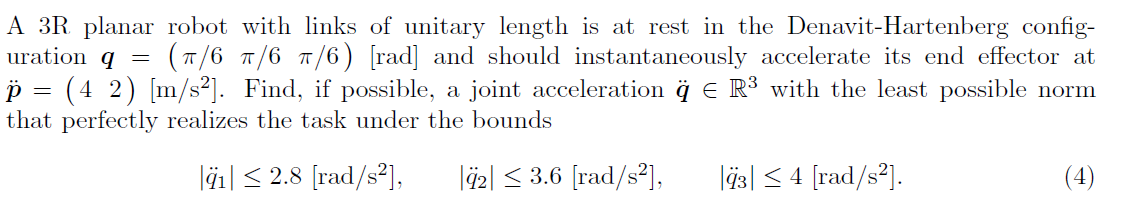

% clear; clc;
% q_d2 = [2.8,3.6,4] % Maximum acceleration constraints of joints
% qnum = 3; %Number of joints
% q = sym('q', [1 qnum],'real');
% d = sym('d', [1 qnum],'real');
% a = sym('a', [1 qnum],'real');
% 
% L = sym('l','real')
% 
% % a, alpha, 
% R3Robot = [L 0 0 q(1);
%            L 0 0 q(2);
%            L 0 0 q(3)]
%        
% T0_EE = getTransformationMatrix(R3Robot)
% 
% % Calculate the Jacobian (Rotational)
% config = 'RRR';
% [Jp, Jo] = getJacobian(R3Robot,config)
% %Jac = [Jp;Jo]
% %Eliminate the zero rows, which represent the unused variables
% Jp = Jp(~all(Jp == 0,2),:)
% 
% q1 = [pi/6, pi/6, pi/6]
% J = subs(Jp, [q L], [q1 1])
% digits(5)
% vpa(J)
% rank(J)

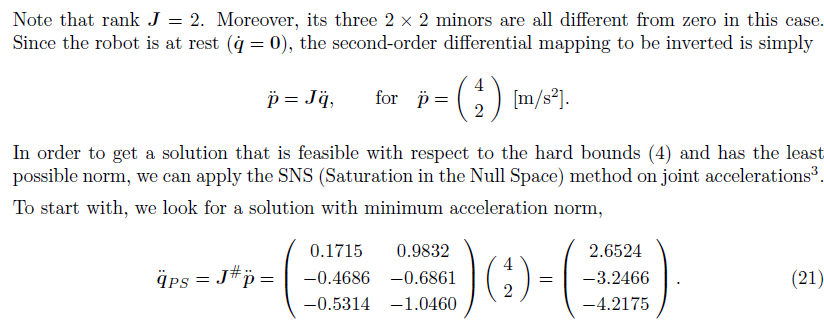

% % SNS
% xdot= [4,2].'
% qdotPS = eval(pinv(J))*xdot
% maxvalue = 1
% qdotstar = qdotPS
% qdot_sns = qdotPS
% while maxvalue > 0
%     [maxvalue, maxindex] = max(abs(qdotstar)-abs(q_d2')) % The positive values are violating the limit. We take the highest one.
%     if (maxvalue > 0) % if there is an exceeding value
%         s = q_d2(1)/qdotstar(maxindex)    
%         %xdot_sns  = xdot - J(:,maxindex)* sign(qdotPS(maxindex))*V(maxindex)
%         %Same as 
%         xdot_sns  = xdot - abs(J(:,maxindex)*q_d2(maxindex));
%         Jtemp = J;
%         Jtemp(:,maxindex) = [];
%         qdot_components = eval(pinv(Jtemp)*xdot_sns).' 
%         qdot_sns = [qdot_components(1:maxindex-1), q_d2(maxindex), qdot_components(maxindex:end)]
%         qdotstar = qdot_sns;
%     else
%         disp("[INFO] No values are exceeding the limits.")
%         disp('Result:')
%         qdotstar
%     end
% end
% 

## DAvid aproach

% V_=[0,12]'
% abs_on=true%this part is important
%  [qdotstarFinal] = SNSMethod1(xdot,vpa(J),q_d2',true)
% 
% [qdotstarFinal,W] = SNSMethod2(xdot,vpa(J),q_d2')%,Qdotmin,Qdotdmax)
% vpa(qdotstarFinal)
% pd2_=vpa(J)*qdotstarFinal
% norm(qdotstarFinal)
% 
% disp("dis last is unfeasible in comparation with the first method")